clear
%%Graph parameters
xmin=-0.1;
xmax=0.1;
ymin=xmin;
ymax=xmax;
zmin=-0.1;
zmax=0.1;

%%inputs
u0=4*pi*10^(-7); %permability
AWG=16;
AWG_d=0.005*92^((36-AWG)/39); %diameter [inches]
insul_thick=0.001; %insulation thickness [inches]
Current=30.0; %[amps]
R0=0.5; %radius to outside of barrel
num_L=5; %number of Layers
num_T=200; %number of Turns overall
segments=50; %points per loop
dx=0.005; %B field step size
%b field calculated by radius of each loop

%%calculations
%spacing is determined initally to be a wire diameter + 2 insul thick
spacing=(AWG_d+2*insul_thick)*(25.4/1000); %[inches]

%%determine circumferences
%circumferences=zeros(1,num_L)
radii=zeros(1,num_L)

radii =      0     0     0     0     0


radii(1,1)=(R0+insul_thick+AWG_d/2)*(25.4/1000)

radii =     0.0134         0         0         0         0


%circumferences(1,1)=2*pi*(R0+insul_thick+AWG_d/2)
for n=2:num_L
    radii(1,n)=(R0+insul_thick+AWG_d/2+2*(insul_thick+AWG_d/2)*(n-1))*(25.4/1000)
    %circumferences(1,n)=2*pi*(R0+insul_thick+AWG_d/2+2*(insul_thick+AWG_d/2)*n)
end

radii =     0.0134    0.0147         0         0         0


radii =     0.0134    0.0147    0.0161         0         0


radii =     0.0134    0.0147    0.0161    0.0174         0


radii =     0.0134    0.0147    0.0161    0.0174    0.0187


%%3d space setup
theta=linspace(0,2*pi,segments)

theta =          0    0.1282    0.2565    0.3847    0.5129    0.6411    0.7694    0.8976    1.0258    1.1541    1.2823    1.4105    1.5387    1.6670    1.7952    1.9234    2.0517    2.1799    2.3081    2.4363    2.5646    2.6928    2.8210    2.9493    3.0775    3.2057    3.3339    3.4622    3.5904    3.7186    3.8468    3.9751    4.1033    4.2315    4.3598    4.4880    4.6162    4.7444    4.8727    5.0009    5.1291    5.2574    5.3856    5.5138    5.6420    5.7703    5.8985    6.0267    6.1550    6.2832


Rx=zeros(num_L,segments) %2d arrays of layers x points

Rx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

Ry=zeros(num_L,segments) %2d arrats of layers x points

Ry =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

Rz=zeros(num_T/num_L,segments) %2d array of layes x points

Rz =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


%iterate to assign radii of circles
for n=1:num_L %for all raddii
    for t=1:segments %fill data points
        Rx(n,t)=radii(1,n)*cos(theta(1,t));
        Ry(n,t)=radii(1,n)*sin(theta(1,t));
    end
end

%iterate to assign height posistion of circles unique as it has to traverse
%all levels

for k=1:num_T/num_L %for all heights
    for t=1:segments %fill data points
        Rz(k,t)=spacing*k;
    end    
end

for k=1:num_T/num_L %for all heights
    for n=1:num_L %for all raddii
        plot3(Rx(n,:),Ry(n,:),Rz(k,:),'Color','k')
        hold on
    end
end
axis([xmin xmax ymin ymax zmin zmax])
xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')

%above here has worked

%%Now B field through biot savart law and derivative estimates
%go at each height, then each ring and each time solve b dield
for k=1:num_T/num_L %for all heights
    for n=1:num_L %for all raddii
        Rx_1=Rx(n,:);
        Ry_1=Ry(n,:)
        Rz_1=Rz(k,:)

        Points=transpose([Rx;Ry;Rz]); %rotate matrix

        x=xmin:dx:xmax; %set array of x
        y=ymin:dx:ymax; %set array of y
        z=zmin:dx:zmax; %set array of z
        %this range to calculate b field
        [X,Y,Z]=meshgrid(x,y,z); %creates 3d grid off of bounds
        
        %%calculations
        Bx=zeros(size(x));
        By=zeros(size(y));
        Bz=zeros(size(z));
        %determine B field by steps of dx

        for t=1:segments-1 %fill data points
            Rx_1=X-Points(t,1);
            Ry_1=Y-Points(t,2);
            Rz_1=Z-Points(t,3);
            R=sqrt(Rx_1.^2+Ry_1.^2+Rz_1.^2); %overall distance to point
            R=R.*(R>=dx)+dx*(R<dx); %rounding for step size

            dLx=Points(t+1,1)-Points(t,1);
            dLy=Points(t+1,2)-Points(t,2);
            dLz=0;

            %components at each point by biot-savart law
            Bx=Bx+u0*Current/(4*pi)*(dLy.*Rz_1-dLz.*Ry_1).*R.^(-3);
            By=By+u0*Current/(4*pi)*(dLz.*Rx_1-dLx.*Rz_1).*R.^(-3);
            Bz=Bz+u0*Current/(4*pi)*(dLx.*Ry_1-dLy.*Rx_1).*R.^(-3);
            
        end  
    end
end

Ry_1 =          0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073   -0.0087   -0.0099   -0.0110   -0.0119   -0.0125   -0.0130   -0.0133   -0.0134   -0.0132   -0.0128   -0.0122   -0.0114   -0.0105   -0.0093   -0.0080   -0.0066   -0.0050   -0.0034   -0.0017   -0.0000


Rz_1 =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


Ry_1 =          0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080   -0.0095   -0.0109   -0.0121   -0.0130   -0.0138   -0.0143   -0.0146   -0.0147   -0.0145   -0.0141   -0.0135   -0.0126   -0.0115   -0.0102   -0.0088   -0.0072   -0.0055   -0.0037   -0.0019   -0.0000


Rz_1 =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


Ry_1 =          0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088   -0.0104   -0.0119   -0.0132   -0.0142   -0.0151   -0.0157   -0.0160   -0.0160   -0.0158   -0.0154   -0.0147   -0.0137   -0.0126   -0.0112   -0.0096   -0.0079   -0.0060   -0.0041   -0.0021   -0.0000


Rz_1 =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


Ry_1 =          0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095   -0.0113   -0.0129   -0.0143   -0.0154   -0.0163   -0.0170   -0.0173   -0.0174   -0.0172   -0.0167   -0.0159   -0.0149   -0.0136   -0.0121   -0.0104   -0.0085   -0.0065   -0.0044   -0.0022   -0.0000


Rz_1 =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


Ry_1 =          0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102   -0.0121   -0.0139   -0.0154   -0.0166   -0.0176   -0.0183   -0.0187   -0.0187   -0.0185   -0.0180   -0.0171   -0.0160   -0.0146   -0.0130   -0.0112   -0.0092   -0.0070   -0.0048   -0.0024   -0.0000


Rz_1 =     0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


Ry_1 =          0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073   -0.0087   -0.0099   -0.0110   -0.0119   -0.0125   -0.0130   -0.0133   -0.0134   -0.0132   -0.0128   -0.0122   -0.0114   -0.0105   -0.0093   -0.0080   -0.0066   -0.0050   -0.0034   -0.0017   -0.0000


Rz_1 =     0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027


Ry_1 =          0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080   -0.0095   -0.0109   -0.0121   -0.0130   -0.0138   -0.0143   -0.0146   -0.0147   -0.0145   -0.0141   -0.0135   -0.0126   -0.0115   -0.0102   -0.0088   -0.0072   -0.0055   -0.0037   -0.0019   -0.0000


Rz_1 =     0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027


Ry_1 =          0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088   -0.0104   -0.0119   -0.0132   -0.0142   -0.0151   -0.0157   -0.0160   -0.0160   -0.0158   -0.0154   -0.0147   -0.0137   -0.0126   -0.0112   -0.0096   -0.0079   -0.0060   -0.0041   -0.0021   -0.0000


Rz_1 =     0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027


Ry_1 =          0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095   -0.0113   -0.0129   -0.0143   -0.0154   -0.0163   -0.0170   -0.0173   -0.0174   -0.0172   -0.0167   -0.0159   -0.0149   -0.0136   -0.0121   -0.0104   -0.0085   -0.0065   -0.0044   -0.0022   -0.0000


Rz_1 =     0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027


Ry_1 =          0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102   -0.0121   -0.0139   -0.0154   -0.0166   -0.0176   -0.0183   -0.0187   -0.0187   -0.0185   -0.0180   -0.0171   -0.0160   -0.0146   -0.0130   -0.0112   -0.0092   -0.0070   -0.0048   -0.0024   -0.0000


Rz_1 =     0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027


Ry_1 =          0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073   -0.0087   -0.0099   -0.0110   -0.0119   -0.0125   -0.0130   -0.0133   -0.0134   -0.0132   -0.0128   -0.0122   -0.0114   -0.0105   -0.0093   -0.0080   -0.0066   -0.0050   -0.0034   -0.0017   -0.0000


Rz_1 =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040


Ry_1 =          0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080   -0.0095   -0.0109   -0.0121   -0.0130   -0.0138   -0.0143   -0.0146   -0.0147   -0.0145   -0.0141   -0.0135   -0.0126   -0.0115   -0.0102   -0.0088   -0.0072   -0.0055   -0.0037   -0.0019   -0.0000


Rz_1 =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040


Ry_1 =          0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088   -0.0104   -0.0119   -0.0132   -0.0142   -0.0151   -0.0157   -0.0160   -0.0160   -0.0158   -0.0154   -0.0147   -0.0137   -0.0126   -0.0112   -0.0096   -0.0079   -0.0060   -0.0041   -0.0021   -0.0000


Rz_1 =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040


Ry_1 =          0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095   -0.0113   -0.0129   -0.0143   -0.0154   -0.0163   -0.0170   -0.0173   -0.0174   -0.0172   -0.0167   -0.0159   -0.0149   -0.0136   -0.0121   -0.0104   -0.0085   -0.0065   -0.0044   -0.0022   -0.0000


Rz_1 =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040


Ry_1 =          0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102   -0.0121   -0.0139   -0.0154   -0.0166   -0.0176   -0.0183   -0.0187   -0.0187   -0.0185   -0.0180   -0.0171   -0.0160   -0.0146   -0.0130   -0.0112   -0.0092   -0.0070   -0.0048   -0.0024   -0.0000


Rz_1 =     0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040    0.0040


Ry_1 =          0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073   -0.0087   -0.0099   -0.0110   -0.0119   -0.0125   -0.0130   -0.0133   -0.0134   -0.0132   -0.0128   -0.0122   -0.0114   -0.0105   -0.0093   -0.0080   -0.0066   -0.0050   -0.0034   -0.0017   -0.0000


Rz_1 =     0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054


Ry_1 =          0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080   -0.0095   -0.0109   -0.0121   -0.0130   -0.0138   -0.0143   -0.0146   -0.0147   -0.0145   -0.0141   -0.0135   -0.0126   -0.0115   -0.0102   -0.0088   -0.0072   -0.0055   -0.0037   -0.0019   -0.0000


Rz_1 =     0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054


Ry_1 =          0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088   -0.0104   -0.0119   -0.0132   -0.0142   -0.0151   -0.0157   -0.0160   -0.0160   -0.0158   -0.0154   -0.0147   -0.0137   -0.0126   -0.0112   -0.0096   -0.0079   -0.0060   -0.0041   -0.0021   -0.0000


Rz_1 =     0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054


Ry_1 =          0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095   -0.0113   -0.0129   -0.0143   -0.0154   -0.0163   -0.0170   -0.0173   -0.0174   -0.0172   -0.0167   -0.0159   -0.0149   -0.0136   -0.0121   -0.0104   -0.0085   -0.0065   -0.0044   -0.0022   -0.0000


Rz_1 =     0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054


Ry_1 =          0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102   -0.0121   -0.0139   -0.0154   -0.0166   -0.0176   -0.0183   -0.0187   -0.0187   -0.0185   -0.0180   -0.0171   -0.0160   -0.0146   -0.0130   -0.0112   -0.0092   -0.0070   -0.0048   -0.0024   -0.0000


Rz_1 =     0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054    0.0054


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080    0.0080


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094    0.0094


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107    0.0107


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134    0.0134


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161    0.0161


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174    0.0174


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188    0.0188


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201    0.0201


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215    0.0215


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228    0.0228


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241    0.0241


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255    0.0255


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268    0.0268


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282    0.0282


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295    0.0295


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309    0.0309


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322    0.0322


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335    0.0335


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349    0.0349


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362    0.0362


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376    0.0376


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389    0.0389


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416    0.0416


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429    0.0429


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443    0.0443


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456    0.0456


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470    0.0470


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483    0.0483


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496    0.0496


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510    0.0510


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523    0.0523


Ry_1 = 1×50
         0    0.0017    0.0034    0.0050    0.0066    0.0080    0.0093    0.0105    0.0114    0.0122    0.0128    0.0132    0.0134    0.0133    0.0130    0.0125    0.0119    0.0110    0.0099    0.0087    0.0073    0.0058    0.0042    0.0026    0.0009   -0.0009   -0.0026   -0.0042   -0.0058   -0.0073


Rz_1 = 1×50
    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537


Ry_1 = 1×50
         0    0.0019    0.0037    0.0055    0.0072    0.0088    0.0102    0.0115    0.0126    0.0135    0.0141    0.0145    0.0147    0.0146    0.0143    0.0138    0.0130    0.0121    0.0109    0.0095    0.0080    0.0064    0.0046    0.0028    0.0009   -0.0009   -0.0028   -0.0046   -0.0064   -0.0080


Rz_1 = 1×50
    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537


Ry_1 = 1×50
         0    0.0021    0.0041    0.0060    0.0079    0.0096    0.0112    0.0126    0.0137    0.0147    0.0154    0.0158    0.0160    0.0160    0.0157    0.0151    0.0142    0.0132    0.0119    0.0104    0.0088    0.0070    0.0051    0.0031    0.0010   -0.0010   -0.0031   -0.0051   -0.0070   -0.0088


Rz_1 = 1×50
    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537


Ry_1 = 1×50
         0    0.0022    0.0044    0.0065    0.0085    0.0104    0.0121    0.0136    0.0149    0.0159    0.0167    0.0172    0.0174    0.0173    0.0170    0.0163    0.0154    0.0143    0.0129    0.0113    0.0095    0.0075    0.0055    0.0033    0.0011   -0.0011   -0.0033   -0.0055   -0.0075   -0.0095


Rz_1 = 1×50
    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537


Ry_1 = 1×50
         0    0.0024    0.0048    0.0070    0.0092    0.0112    0.0130    0.0146    0.0160    0.0171    0.0180    0.0185    0.0187    0.0187    0.0183    0.0176    0.0166    0.0154    0.0139    0.0121    0.0102    0.0081    0.0059    0.0036    0.0012   -0.0012   -0.0036   -0.0059   -0.0081   -0.0102


Rz_1 = 1×50
    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537    0.0537


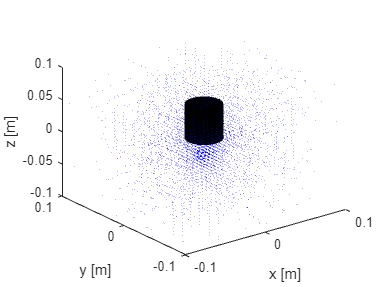

quiver3(X,Y,Z, Bx,By,Bz,'b')

% 
% %This is a simulation to model a video found to do stacked loops such as a
% %solenoid found at 
% %https://www.youtube.com/watch?v=mJfdboA4iME&ab_channel=KurtOwen
% % clear
% % clf
% % %%set parameters
% % I=1.0; %[Amps]
% % u0=4*pi*10^(-7); %permability
% % 
% % nR=50; %number of segments
% 
% %%graph window
% % xmin=-0.02;
% % xmax=0.02;
% % ymin=xmin;
% % ymax=xmax;
% % zmin=xmin;
% % zmax=xmax;
% % dx=0.005; %step size for grid
% % 
% % nloops=16; %number of loops [per layer]
% % spacing=.8*(zmax-zmin)/nloops; %will be swaped for wire parameter spacing
% % zlow=-0.5*((nloops-1)*spacing);
% 
% % %%initialize vectors
% % theta=linspace(0,2*pi,nR+1);
% % Rx=R0*cos(theta); %x points on loops by radius
% % Ry=R0*sin(theta); %y points on loops by radius
% % Rz=zlow*ones(1,nR+1); 
% % 
% % Points=transpose([Rx;Ry;Rz]); 
% % 
% % x=xmin:dx:xmax;
% % y=ymin:dx:ymax;
% % z=zmin:dx:zmax;
% % 
% % [X,Y,Z]=meshgrid(x,y,z); %creates 3d grid
% % 
% % %%calculations
% % Bx=zeros(size(x));
% % By=zeros(size(y));
% % Bz=zeros(size(z));
% % for jt=1:nloops %for number of turns per layer
% %     for it=1:nR
% %         Rx=X-Points(it,1);
% %         Ry=Y-Points(it,2);
% %         Rz=Z-Points(it,3);
% % 
% %         R=sqrt(Rx.^2+Ry.^2+Rz.^2); %overall distance to point
% %         R=R.*(R>=dx)+dx*(R<dx); %rounding for step size
% % 
% %         dLx=Points(it+1,1)-Points(it,1);
% %         dLy=Points(it+1,2)-Points(it,2);
% %         dLz=0;
% % 
% %         %components at each point by biot-savart law
% %         Bx=Bx+u0*I/(4*pi)*(dLy.*Rz-dLz.*Ry).*R.^(-3);
% %         By=By+u0*I/(4*pi)*(dLz.*Rx-dLx.*Rz).*R.^(-3);
% %         Bz=Bz+u0*I/(4*pi)*(dLx.*Ry-dLy.*Rx).*R.^(-3);
% %     end
% %     
% %     axis([xmin xmax ymin ymax zmin zmax])
% %     hold on
% %     quiver3([-1.1*R0,1,1*R0],[.2*R0,-.2R0])
% % end
% % quiver3(X,Y,Z, Bx,By,Bz,'b')
% % hold off
% % rotate3d on
% % 
% % xlabel('x [m]')
% % ylabel('y [m]')
% % zlabel('z [m]')
% % view(-30,15)
% % title('b-field visualization')